# Lab A: Machine Learning for Classification

## Classification problem: 

Classification is a task that requires the use of machine learning algorithms that learn how to assign a class label to examples from the problem domain. An easy-to-understand example is classifying emails as “spam” or “not spam.”

There are many different types of classification tasks that you may encounter in machine learning and specialized approaches to modeling that may be used for each. In this tutorial, we try to solve a binary classification problem. Binary classification refers to predicting one of two classes and multi-class classification involves predicting one of more than two classes.

For example, assume we have a random set of circles and triangles distributed in 2D spaces and we want to find a line that separates them. I mean one side of the line we see just circles and on the other side we see triangles as shown in the below figure,

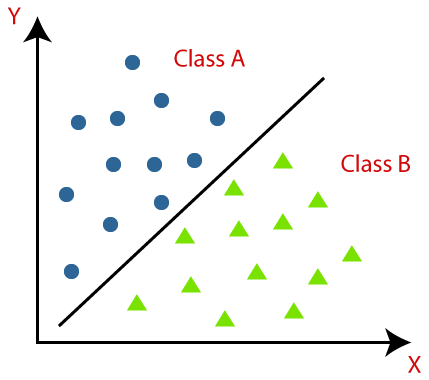

This problem is called classification, and here we are going to drive a mathematical solution for how we can separate these circles and triangles (we call them classes).

## Problem 1 

In the previous prelab we described how we can generate random points in 2D spaces with different statistical properties. Here we are going to recreate this dataset for a classification problem.

First, generate two sets of 1000  points for two different means  and the same standard deviation  in different colors

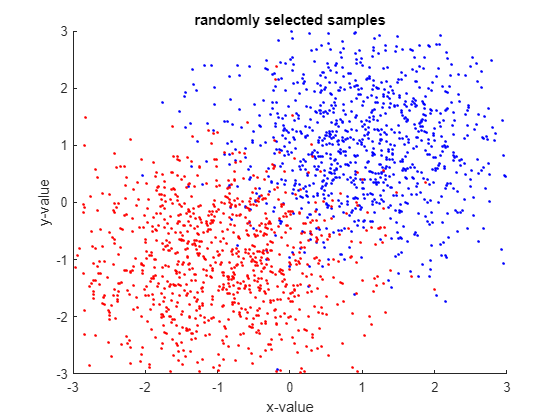

% define some constant parameters we'll use later
sz=1000;
mu_x=[1.0,-1.0];
std_x=1;

% generate two random gaussian distributions
x1=std_x* randn(sz,1)+ mu_x(1);
y1=std_x* randn(sz,1)+ mu_x(1);

x2=std_x* randn(sz,1)+ mu_x(2);
y2=std_x* randn(sz,1)+ mu_x(2);    

% plotting
figure;
h_ax = gca;
hold(h_ax, "on")

plot(h_ax, x1,y1, '.b');
plot(h_ax, x2,y2, '.r');

h_ax.Title.String = 'randomly selected samples';
h_ax.XLabel.String = 'x-value';
h_ax.YLabel.String = 'y-value';

h_ax.XLim = [-3,3];
h_ax.YLim = [-3,3];

Here we want to combine these two sets of data and create a vector called **input** with size 2000$\times \;$2 which the first 1000 elements are concatenations of x1,y1, and the rest are the concatenation of x2,y2.

As you remember we defined two colors for the sample points red and blue, now we want to create a vector called **output** with size 2000 $\times \;\;$1 in which:

- if the color is red then its corresponding element in output is 1 and;

- if the color is blue then its corresponding element is 0. 

input = [ [x1 y1]; [x2 y2] ];   % ← define this variable
output = [ [ones(1000,1)]; [zeros(1000,1)] ];  % ← define this variable

% double check sizes
size(input), size(output)

ans =         2000           2


ans =         2000           1


## Problem  2

Now we want to find a  nonlinear combination of the input vector ($\left.\mathit{\mathbf{x}}\right)$ elements defined as $\hat{\;y\;} =\sigma \;\left({\mathit{\mathbf{a}}}_{1\;} \times {\mathit{\mathbf{x}}}_{1\;} +{\mathit{\mathbf{a}}}_{2\;} \times {\mathit{\mathbf{x}}}_{2\;} \right)=\sigma \;\left(\textrm{Ax}\right)$, which is able to predict a label for each entry. Notice that the actual label (the true label) for each entry is in the output vector ($y$). 

**hint**: $\sigma \;\left(x\right)=\frac{1}{\;1+e^{\left(-x\right)} }\;$ is called sigmoid function.

define a sigmoid function with **mysigmoid **name and test it with the below code

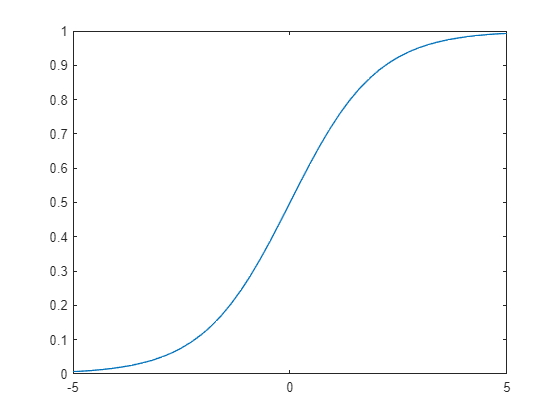

%%% note: you do not need to change the code below. %%%
%%%       it will just work if your function is     %%%
%%%       correctly defined.                        %%%
x = [-10;10];
fplot(@(x) myfunc_sigmoid(x))  % plot our sigmoid function from -10 to 10 to double-check

## Problem 3

Now we investigate the rule of the parametrs ($\left.a_{1\;} ,a_{2\;} \right)$in performance of the classifier. To investigate the effect of the model's parameters on the classifier performance we need to define the classifier error for all samples in predicting their classes. To do that, we define error function  as


$$E=\frac{1}{N\;}\sum_{i=1}^{N=2000} {\left(\sigma \;\left({\textrm{Ax}}_{i\;} \right)-y_{i\;} \right)}^{2\;}$$


 In this part of the problem we will select a range of possible values for each parameters  and calculate the error function for that. We use a Grid-search method to do that. This method iteratively changes values of the parameters and calculates the error function.  write a code that calculates for a range of 201 samples from -10 to 10 for each weight ($\left.a_{1\;} \;\textrm{and}\;a_{2\;} \right)$.  

a1 = 20*randn(1,201) - 10;
a2 = 20*randn(1,201) - 10;
A = [a1; a2];

Now use surf function to show the error value against two sets of parameters ($\left.a_{1\;} \;\textrm{and}\;a_{2\;} \right)$. What is your inference about this plot surface?

C = (1/2000 * (myfunc_sigmoid(A*input(1:201,1)) - input(1:201,2)))

Error using  ^  (line 52)
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To perform elementwise matrix powers, use '.^'.

E = dot(C,C)
figure
surf(a1,a2,E)
xlabel('a1')
ylabel('a2')
zlabel('E')

As you should see the value of the error function is different for the combinations of the model parameters. A general intuition is a classifier with parameters set that lead to a lower error value, is more accurate for the classification problem.

## Problem 4

We also can calculate the classifier accuracy. To do that, we need to define accuracy function as


$$\textrm{accuracy}=\frac{\textrm{Number}\;\textrm{of}\;\textrm{correct}\;\textrm{prediction}}{\textrm{Total}\;\textrm{number}\;\textrm{of}\;\textrm{predictions}}*100$$


And measure the classifer accuracy for a specific set of parameters. 

You need to define a function that called **myaccuracy** which get the predicted labels ($\hat{\;y\;}$) and the true ones (the output vector) and return the percentage of true predicted labels and test it with the below code

acc = myfunc_accuracy(output,output)

## Problem 5

As we discussed a classifier with a small error is a better classifier in sense of performance. As a result, it should have higher accuracy. We want to test this scenario. To do that, select a set of parameters from a region in the previous surface plot with a small error value. then calculate the accuracy of your classifier with the function you wrote in the previous problem.

%a1=% your selection
%a2=% your selection
yhat=mysigmoid(a1*input(:,1)+a2*input(:,2));
yhat(yhat>=.5)=1;
yhat(yhat<.5)=0;
acc=myaccuracy(yhat,output)

Again select a set of parameters from a region in the previous surface plot with a large error value. then calculate the accuracy of your classifier with the function you wrote in the previous problem.

%a1=% your selection
%a2=% your selection
yhat=mysigmoid(a1*input(:,1)+a2*input(:,2));
yhat(yhat>=.5)=1;
yhat(yhat<.5)=0;
acc=myaccuracy(yhat,output)

What is your inference about these two results? Did these results support the hypothesis we had at the begining of this problem?

## Functions

define the **myfunc_sigmoid** and **myfunc_accuracy** functions here

function f = myfunc_sigmoid(x)
    f = 1 / (1 + exp(-x));
end


%function out = myfunc_accuracy(yhat,y)

%end